# 1. Processat + Segmentació + Etiquetat + Descripció de regions

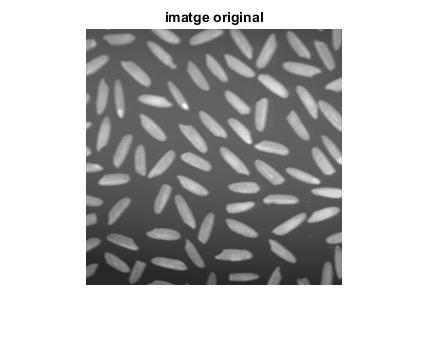

clear,close all
orig = imread ('arros.tif');
imshow(orig), title('imatge original')

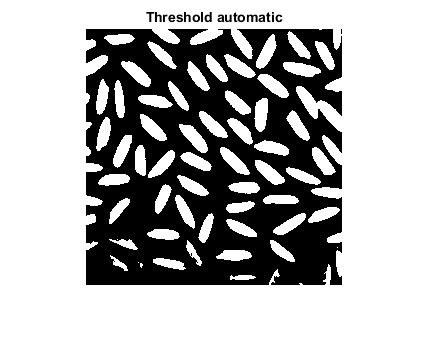

% segmentem per binarització
bw=im2bw(orig, graythresh(orig)); % Binarització per Otsu
figure, imshow(bw),title('Threshold automatic')

No funciona, perdem grans. No confieu mai en els detectors automatics de llindar. El problema està en que la iluminació no és gens homogènea

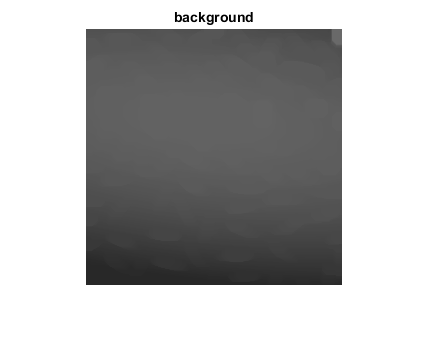

% Fem un filtratge morfològic
bg = imopen(orig,strel('disk',10));
figure, imshow(bg),title('background')

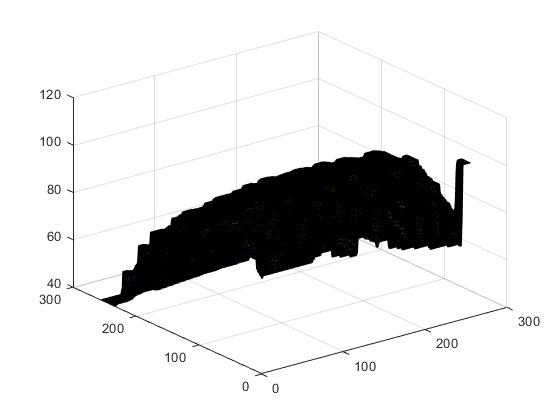

figure, surf(bg) % mostrem el background com si fos una superfície

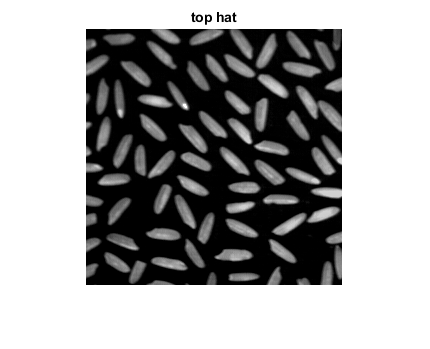

%Li restem el background a la imatge
y = imsubtract(orig,bg);
figure, imshow(y, []), title( 'top hat')

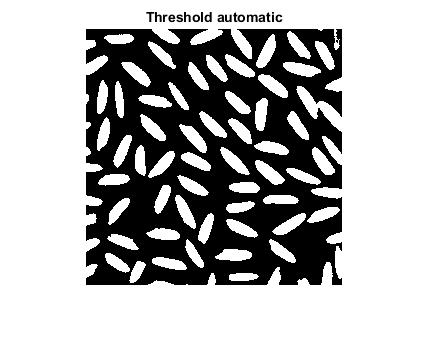

% tornem a segmentar per Otsu
bw=im2bw(y, graythresh(y));
figure, imshow(bw),title('Threshold automatic')

Ara si!

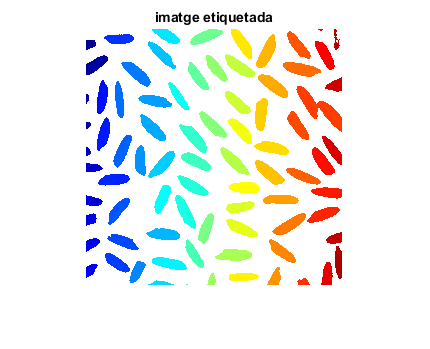

% etiquetem la imatge segmentada
[eti num] = bwlabel(bw,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')

% Comptem ara el nombre d’objectes a la imatge
num

num = 81

%o be:
max(eti(:))

ans = 81

% obtenim descriptors de les regions
Dades=regionprops(eti,'all');

Comproveu en el workspace la variable Dades. Quines propietats hem extret de cada regió? Consulteu el help de la funció regionprops.

 % Podem obtenir una dada de l’objecte 50 de la forma:
Dades(50).Area

ans = 305

% O be un vector amb totes les Àrees:
Arees=[Dades.Area];

**Exercici**: en la imatge segmentada, separeu els grans d’arròs que es toquen. Desprès elimineu els grans d’arròs que toquen les vores. Tots aquests grans falsejaven el resultat. Amb la nova imatge etiquetatda, obteniu les propietats que us semblin adients usant regionprops. Representeu mitjançant plots o diagrames de barres aquelles propietats que us semblin interessants per a fer un control de qualitat dels grans d’arròs.

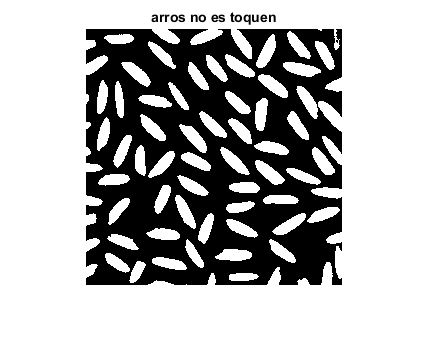

bw = imcomplement(bw);
D = -bwdist(bw);
mask = imextendedmin(D,2);
D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
bw(Ld2 == 0) = 255;
bw = imcomplement(bw);
imshow(bw), title('arros no es toquen');

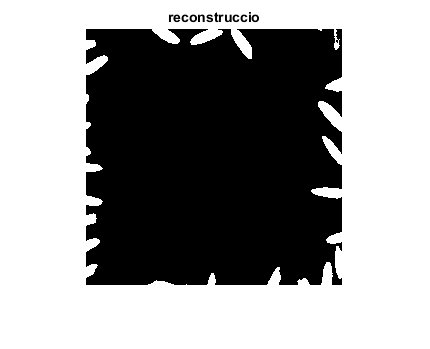

mark = true(size(bw));
mark(2:end-2,2:end-1) = 0;
dilc = imreconstruct(mark,bw);
imshow(dilc), title('reconstruccio')

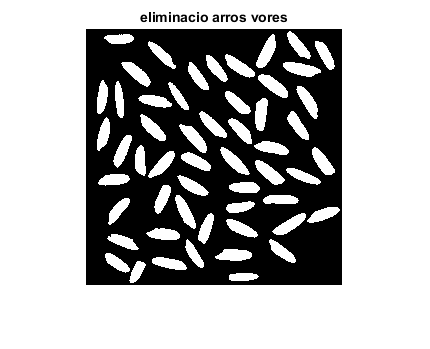

bw = xor(dilc,bw);
imshow(bw), title('eliminacio arros vores')

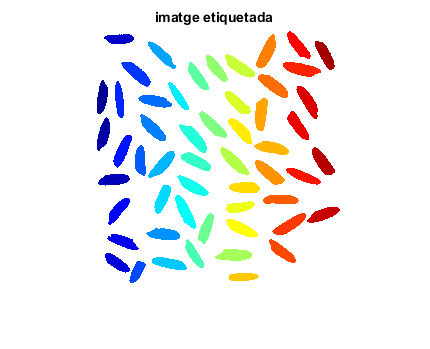

[eti num] = bwlabel(bw,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')

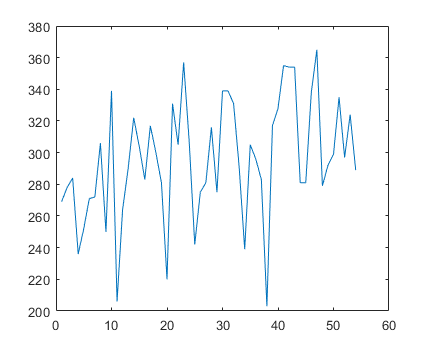

% obtenim descriptors de les regions
Dades=regionprops(eti,'all');
% O be un vector amb totes les Àrees:
Arees=[Dades.Area];
% 
h = plot(Arees);

## 2. Codis de cadena

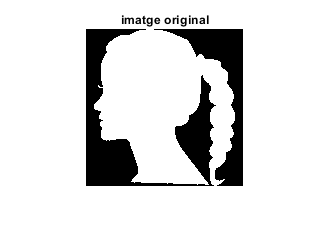

clear all, close all
im=imread('head.png');
% no cal tan gran
im=imresize(im,1/4);
imshow(im), title('imatge original')

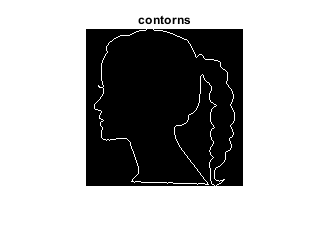

% obtenim el contorn
ero=imerode(im,strel('disk',1));
cont=xor(ero,im);
figure,imshow(cont), title('contorns')

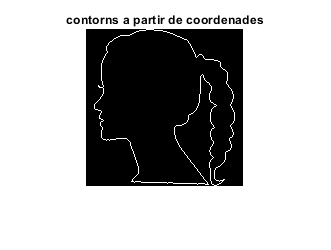

% obtenim les coordenades del contorn
[fila col] = find(im,1); % Busquem el primer píxel
B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
% B conté les coordenades
% Ho comprovem mostrant el resultat
aux=zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
figure,imshow(aux),title ('contorns a partir de coordenades')

**Exercici**t**:** trobar els codis de cadena incrementals a partir de B

[row, ~] = size(B);
row

row = 755

%2  3   4
%1      5
%0      6
cadena = zeros(row,1)-1;
rActual = (B(1,:)-B(2,:));
for i=2:row-1
    rNext = (B(i,:)-B(i+1,:));
    B1 = atan2d(rActual(1)*rNext(2)-rActual(2)*rNext(1), dot(rActual,rNext));
    if B1 == 0
       cadena(i-1) = 3;
    elseif B1 == 45
       cadena(i-1) = 2;        
    elseif B1 == 90
       cadena(i-1) = 1;        
    elseif B1 == 135
       cadena(i-1) = 0;        
    elseif B1 == -45
       cadena(i-1) = 4;        
    elseif B1 == -90
       cadena(i-1) = 5;        
    elseif B1 == -135
       cadena(i-1) = 6;        
    end
    rActual = rNext;
end

rNext = (B(end,:)-B(1,:));
B1 = atan2d(rActual(1)*rNext(2)-rActual(2)*rNext(1), dot(rActual,rNext));
if B1 == 0
   cadena(end-1) = 3;
elseif B1 == 45
   cadena(end-1) = 2;        
elseif B1 == 90
   cadena(end-1) = 1;        
elseif B1 == 135
   cadena(end-1) = 0;        
elseif B1 == -45
   cadena(end-1) = 4;        
elseif B1 == -90
   cadena(end-1) = 5;        
elseif B1 == -135
   cadena(end-1) = 6;        
end



## 3. Descriptors de Fourier

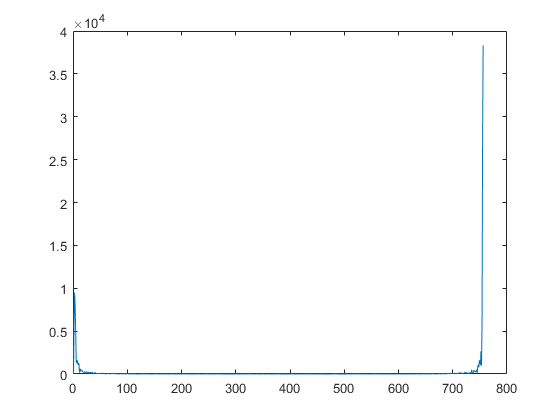

% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);
% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);
% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
s(end+1,:)=s(end,:); %dupliquem l'ultim
mida=mida+1;
end
% Calculem la Fast Fourier Transform
z=fft(s);
% representem l’espectre
figure,plot(abs(z))

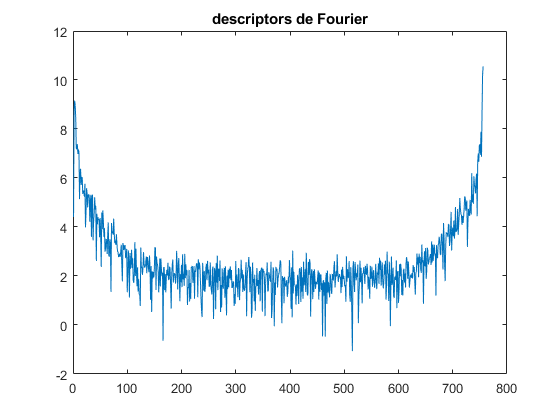

% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')

Observeu que l’espectre surt duplicat, amb un efecte mirall. És una propietat de la trasnformada de Fourier, que ara no ve al cas.

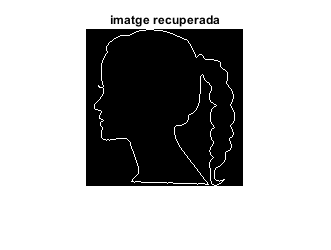

% Recuperem la imatge original per comprovar que el procés és reversible
ss=ifft(z); % Transformada de Fourier inversa
files= round(real(ss)+mig(1));
cols=round(imag(ss)+mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('imatge recuperada')

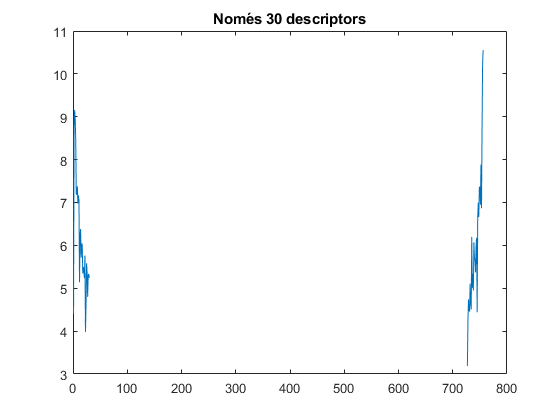

%% Reduim la quantitat de descriptors de Fourier
N=30; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')

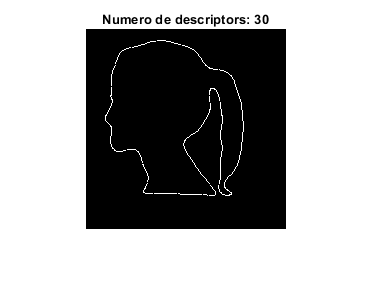

% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

**Exercici:** Repetiu el procés utilitzant diferents quantitats de descriptors i expliqueu quin efecte té això en el detall de la imatge obtinguda